Read data

T = readtable('stock1.xlsx', 'Sheet', 2);

Stock's of Company name

symbol = T.Properties.VariableNames(2:end)'

symbol = 46×1 cell array
    {'AAPL' }
    {'AEP'  }
    {'AMT'  }
    {'AMZN' }
    {'CLF'  }
    {'CLX'  }
    {'COST' }
    {'CVX'  }
    {'D'    }
    {'DUK'  }
    {'DXCM' }
    {'ECL'  }
    {'ELF'  }
    {'ES'   }
    {'EXR'  }
    {'FDX'  }
    {'GOOGL'}
    {'HAL'  }
    {'HD'   }
    {'HSY'  }
    {'JPM'  }
    {'KDP'  }
    {'KIM'  }
    {'LHX'  }
    {'LIN'  }
    {'MPC'  }
    {'MS'   }
    {'MSFT' }
    {'NEE'  }
    {'NFLX' }


Calculate the quarter return of original table

quarterlyReturn =T{:,2:end}

quarterlyReturn =     0.0977   -0.0976   -0.2451    0.1562   -0.3819   -0.0101    0.0437   -0.0231   -0.0693   -0.0685    0.1513   -0.0793    0.1560   -0.1649   -0.1795    0.0466    0.1166   -0.0949   -0.0461   -0.1235    0.1416   -0.1577    0.0248   -0.1610   -0.1312   -0.1819    0.1759    0.0039   -0.1815    0.2078    0.1820    0.0183   -0.0641   -0.1687   -0.0692   -0.2693   -0.0562   -0.1175   -0.0137   -0.1790   -0.1303   -0.1487    0.1233   -0.2013   -0.1058    0.1124
    0.0708    0.1570    0.1657   -0.0583   -0.2052    0.1830    0.0474   -0.0510    0.1790    0.1463   -0.6732    0.0798   -0.8725    0.1778    0.1645   -0.0860   -0.1020   -0.1443    0.1753    0.0552    0.0310    0.1293    0.1788    0.0715    0.1031   -0.0677    0.0571   -0.0595    0.1784    0.0503    0.1179    0.1322    0.0386    0.1201    0.1827    0.0711   -0.0945    0.2266    0.2187    0.1620    0.1997    0.1570    0.0445    0.1002    0.0271   -0.0311
    0.1938    0.0455    0.0240    0.0635   -0.4743   -0.1021

Build a portfolio with 1% risk rate annually 

p = Portfolio('AssetList',symbol,'RiskFreeRate',0.01/4);
p = estimateAssetMoments(p, quarterlyReturn);
p = setDefaultConstraints(p);

Estimate optimal portfolio (Max Sharpe Ratio)

w1 = estimateMaxSharpeRatio(p)

w1 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.5907
    0.0000
    0.0000
    0.0000


[risk1, ret1] = estimatePortMoments(p, w1)

risk1 = 0.0756

ret1 = 0.0483

## **The code for Data Visualization is from MATLAB reference**

## **Data Visualization**

Plot the risk and expected return of all asset in the portfolio

f = figure;
tabgp = uitabgroup(f); % Define tab group
tab1 = uitab(tabgp,'Title','Efficient Frontier Plot'); % Create tab
ax = axes('Parent', tab1);
% Extract asset moments from portfolio and store in m and cov
[m, cov] = getAssetMoments(p); 
scatter(ax,sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.
xlabel('Risk')
ylabel('Expected Return')
text(sqrt(diag(cov))+0.0003,m,symbol,'FontSize',7); % Label ticker names

Plot optimal portfolio and efficient frontier using `plotFrontier`

hold on;
[risk2, ret2]  = plotFrontier(p,10);
plot(risk1,ret1,'p','markers',15,'MarkerEdgeColor','k',...
                'MarkerFaceColor','y');
hold off

Visualize table in MATLAB

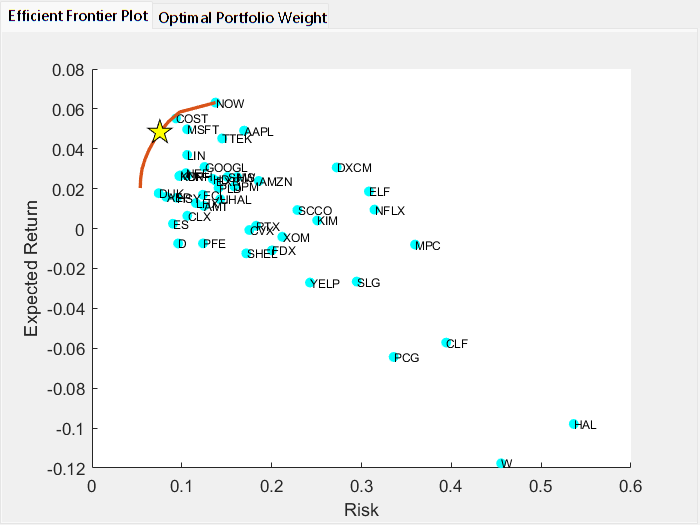

tab2 = uitab(tabgp,'Title','Optimal Portfolio Weight'); % Create tab

% Column names and column format
columnname = {'Ticker','Weight (%)'};
columnformat = {'char','numeric'};

% Define the data as a cell array
% Filter for assets with non-zero weights and ensure column vectors
nonZeroIdx = w1 > 0;
tickers = symbol(nonZeroIdx)';
weights = w1(nonZeroIdx) * 100;

% Force both to be column vectors
tickers = tickers(:);
weights = weights(:);

% Combine into table and convert to cell
data = table2cell(table(tickers, weights));

% Create the uitable
uit = uitable(tab2, 'Data', data,... 
            'ColumnName', columnname,...
            'ColumnFormat', columnformat,...
            'RowName',[]);

% Set width and height
uit.Position(3) = 450; % Widght
uit.Position(4) = 350; % Height